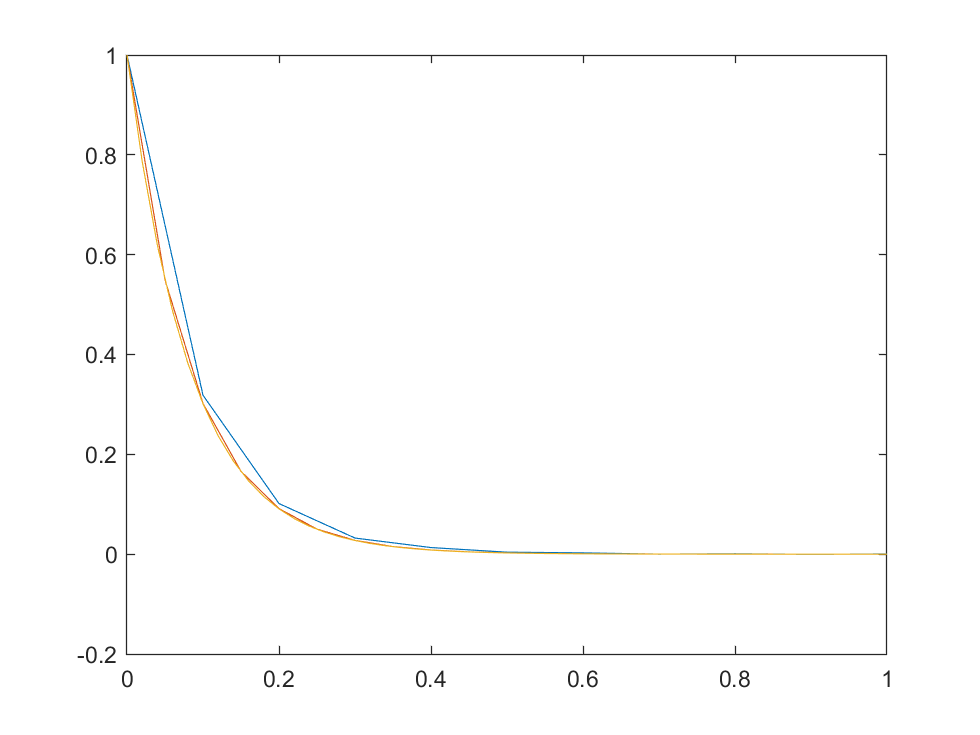

f =@(t,y) (-12*y);
F =@(t) (exp(-12*t));

a = 0;
b = 1;

alpha = 1;

N = [10,20,50];

y9 = AM4(f,a,b,alpha,N(1,1));
y10 = AM4(f,a,b,alpha,N(1,2));
y11 = AM4(f,a,b,alpha,N(1,3));

x9 = (b-a)/N(1,1);
x10 = (b-a)/N(1,2);
x11 = (b-a)/N(1,3);

t9 = a:x9:b;
t10 = a:x10:b;
t11 = a:x11:b;

t9 = t9';
t10 = t10';
t11 = t11';

plot(t9,y9,t10,y10,t11,y11);

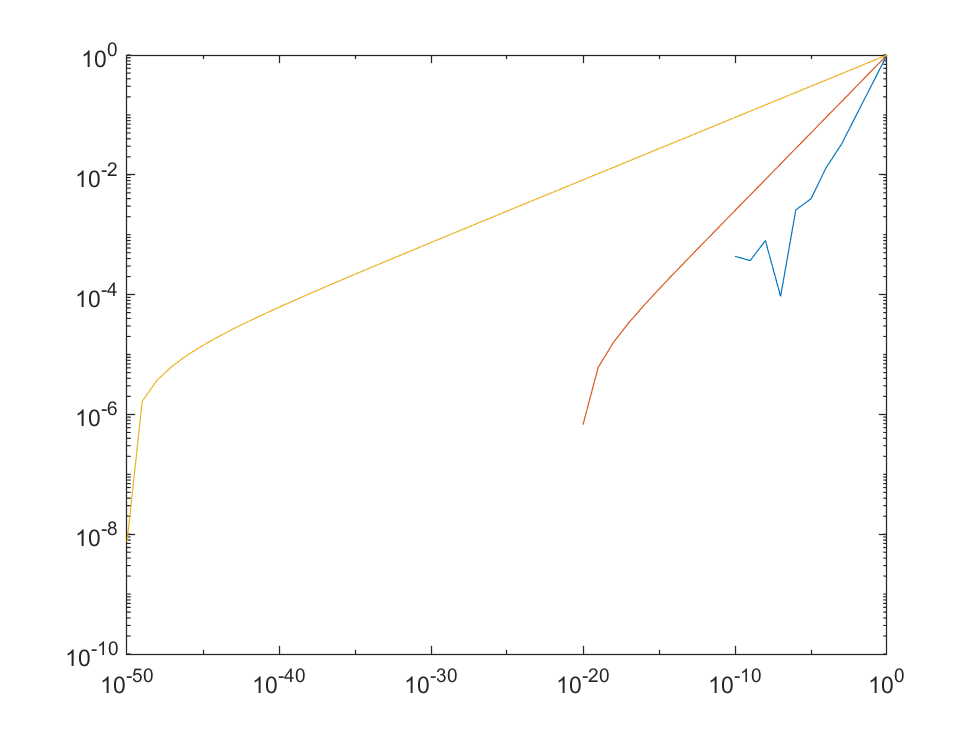


% the answer gets more accurate as the number of intervals increases

syms y(t)
eqn = diff(y,t) == (-12*y);
cond = y(0) == alpha;
ySol(t) = dsolve(eqn,cond);

eans = vpa(ySol(1));

syms t
eqn = exp(-12*t) == eans;
solx = solve(eqn,t);

h9 = ones(1,N(1,1)+1);
h10 = ones(1,N(1,2)+1);
h11 = ones(1,N(1,3)+1);

err9 = ones(1,N(1,1)+1);
err10 = ones(1,N(1,2)+1);
err11 = ones(1,N(1,3)+1);

% absolute error of 20 intervals
for i = 1:N(1,1)+1
    h9(1,i) = 10^(1-i);
    err9(1,i) = abs(eans-y9(i,1));
end

% absolute error of 50 intervals
for i = 1:N(1,2)+1
    h10(1,i) = 10^(1-i);
    err10(1,i) = abs(eans-y10(i,1));
end

% absolute error of 100 intervals
for i = 1:N(1,3)+1
    h11(1,i) = 10^(1-i);
    err11(1,i) = abs(eans-y11(i,1));
end

loglog(h9,err9);
hold on;
loglog(h10,err10);
loglog(h11,err11);
hold off;


Err3 = [err9(1,N(1,1)+1),err10(1,N(1,2)+1),err11(1,N(1,3)+1)];

% the error decreases as the number of intervals increases
% the method appears to be converging


function [y] = AM4(f,a,b,alpha,N)
    h = (b-a)/N;
    x = a:h:b;
    sx = size(x,2);
    y = ones(1,sx);
    y(1,1) = alpha;
    for i = 2:N+1
        k1 = h*f(x(1,i-1),y(1,i-1));
        k2 = h*f(x(1,i-1) + (h/2),y(1,i-1) + (k1/2));
        k3 = h*f(x(1,i-1) + (h/2),y(1,i-1) + (k2/2));
        k4 = h*f(x(1,i),y(1,i-1) + k3);
        y(1,i) = y(1,i-1) + (k1/6) + (k2/3) + (k3/3) + (k4/6);
    end
    for i = 5:N+1
        f1 = f(x(1,i-4),y(1,i-4));
        f2 = f(x(1,i-3),y(1,i-3));
        f3 = f(x(1,i-2),y(1,i-2));
        f4 = f(x(1,i-1),y(1,i-1));
        f5 = f(x(1,i),y(1,i));
        y(1,i) = y(1,i-1) + h*((251/720)*f5 + (646/720)*f4 - (264/720)*f3 ...
            + (106/720)*f2 - (19/720)*f1);
    end
    y = y';
end
